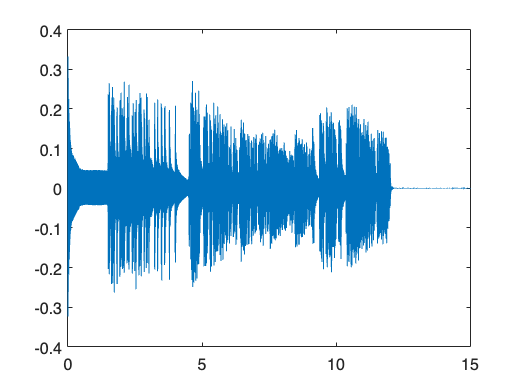

load('long_modem_rx.mat')
start_idx = find_start_of_signal(y_r, x_sync);
y_t = y_r(start_idx+length(x_sync):end);
t = 0:(1/Fs):(length(y_t)-1)/Fs;
plot(t,y_t)

soundsc(y_t,Fs)

W = f_c;
c = cos(2*pi*f_c*t);

y_c = c .* y_t';
%w = linspace(-Fs*pi,Fs*pi-2*pi*Fs/length(Y_c),length(Y_c));
% M = Y_c(abs(w) < f_c/Fs);
% 
%hel w_crop = w(abs(w) < f_c/Fs);
% m = ifft(M);

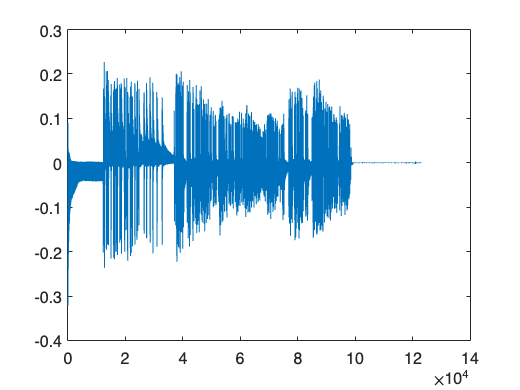

plot(y_c)

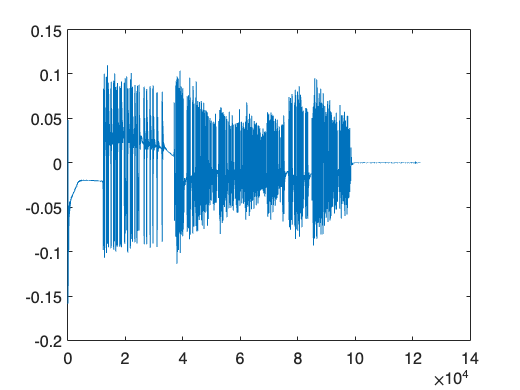

y_l = lowpass(y_c, f_c/Fs);
m = zeros([msg_length*8, 1]);
for i=1:length(m)
    average = mean(y_c((i-1)*100+1:i*100));
    m(i) = average > 0;
end
% SINC ???
plot(y_l)


soundsc(y_l, Fs)

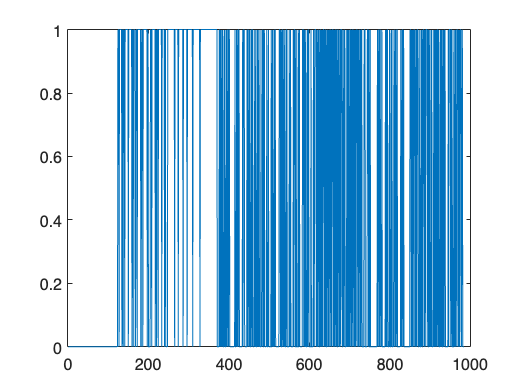

plot(m)

%soundsc(m_down, Fs)

BitsToString(m)

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'

plot(y_l)

function [X, w] = plot_ft_rad(x, fs)
    % Plots the magnitude of the Fourier transform of the signal x
    % that is assumed to originate from a Continous-time signal
    % sampled with frequency fs.
    % The function returns X and f.
    % In other words, this function plots the FT of the DT signal x
    % with the frequency axis labeled as if it were the original CT
    % signal.
    %
    % X contains the frequency response
    % w contains the frequency samples
    N = length(x);
    X = fftshift(fft(x));
    %
    %
    %
    %
    %
    w = linspace(-fs/2*2*pi, 2*pi*fs/2- 2*pi*fs/length(x),length(x));
    plot(w, abs(X));
    xlabel('Frequency (rad/s)');
    ylabel('|X(j\omega)|');
end
